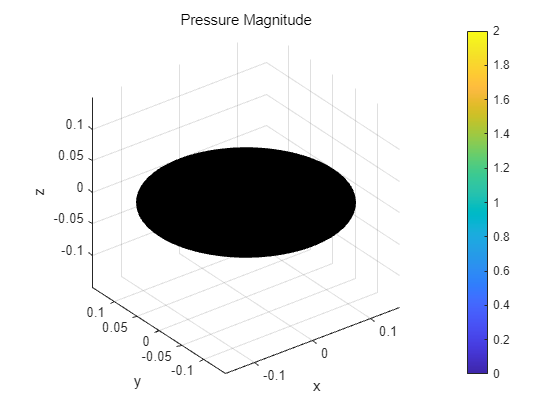

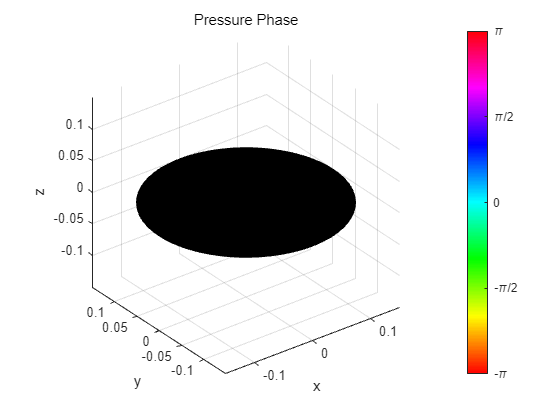

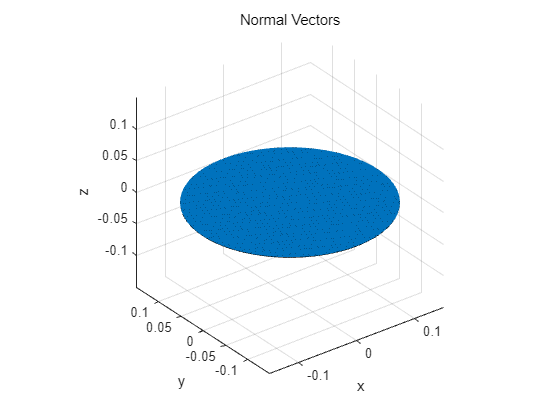

%% Transducer Design
transducer_info = [];

transducer_info.Frequency = 40000;
transducer_info.Pressure = 1;
transducer_info.Phase = 0;
transducer_info.Type = 'circle';
transducer_info.Radius = 0.15;
transducer_info.medium = 'air';

transducer_object = PFC_Make3DTransducer(transducer_info);

PFC_DrawTransducer3D(transducer_object, '-');


%% Frequency Domain
input_source = [];

input_source.Type = 'frequency';
input_source.reading_list = 40000; % [Hz]



%% Simulation Space
reading_pos_x = -150e-3 : 5e-3 : 150e-3;          % Simulation Area
reading_pos_y = -150e-3 : 5e-3 : 150e-3;          % Simulation Area
reading_pos_z = 0e-3 : 5e-3 : 3000e-3;          % Simulation Area



%% Run Frequency Domain Simulation

% xz plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, 0, reading_pos_z);

Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));
Pressure_dxyz_i_rot = rot90(Pressure_dxyz_i, -1);

figure;imagesc(reading_pos_x.*1e3, reading_pos_z.*1e3, Pressure_dxyz_i_rot);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top', 'YDir', 'normal');
title('View of Pressure Fleid in XZ plane at y = 5mm');
colorbar;
colormap(hot);
xlabel('x [mm]');
ylabel('z [mm]');

row_data = Pressure_dxyz_i(31, :);
plot(row_data);
xlabel('Z-index');
ylabel('Gain');
title('Gain graph at Center');
grid on;
xlim([0 200])



% xy plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, reading_pos_y, 0.2);

Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top','YDir', 'normal');
title('View of Pressure Fleid in XY plane at z = 20mm');
colorbar;
colormap(hot);
xlabel('x [mm]');
ylabel('y [mm]');

